# Exercício 3 e 4

clear all;
clc;
close all;



## Sinal em análise g(t)

T0= 1                          % período

T0 = 1

f0 = 1/T0

f0 = 1

w0 = 2*pi*f0

w0 = 6.2832


gt = @(t) (exp(-t));
gnt = @(w0,n,t) exp(-j*n*w0*t);


## Análise de fourier

syms n t tempo

c1= int(gt(t) * gnt(w0,1,t) ,t,0,T0) / ( int(gnt(w0,1,t)* gnt(-w0,1,t),t,0,T0) )

$$c1 = -\frac{{\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right)\,\mathrm{i}}{2\,\pi -\mathrm{i}}$$

c_1 = int(gt(t) * gnt(w0,-1,t) ,t,0,T0) / ( int(gnt(w0,-1,t) * gnt(-w0,-1,t) ,t,0,T0) )

$$c\_1 = -\frac{{\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right)}{-1+2\,\pi \,\mathrm{i}}$$


resc1 = eval(c1)

resc1 = 0.0156 - 0.0981i

resc_1 = eval(c_1)

resc_1 = 0.0156 + 0.0981i


p1t = @(tempo) c1 * exp(-j*w0*tempo) + c_1*exp(j*w0*tempo)

p1t = function_handle with value:
    @(tempo)c1*exp(-j*w0*tempo)+c_1*exp(j*w0*tempo)



r1t = @(tempo) gt(tempo) - p1t(tempo)

r1t = function_handle with value:
    @(tempo)gt(tempo)-p1t(tempo)


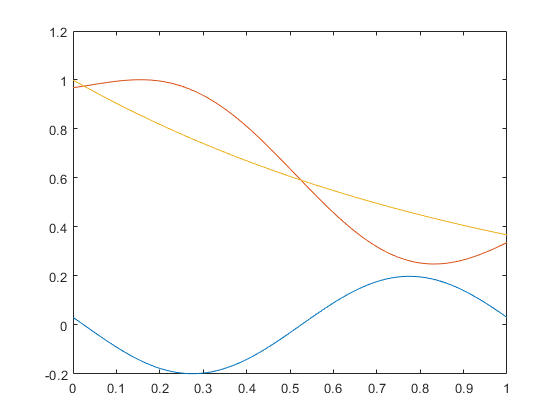


tempo = [0:0.01:T0];

figure()
plot(tempo,p1t(tempo) ,tempo,r1t(tempo) ,tempo,gt(tempo))

## Ex 4


c2= int(gt(t) * gnt(w0,2,t) ,t,0,T0) / ( int(gnt(w0,2,t)* gnt(-w0,2,t),t,0,T0) )

$$c2 = -\frac{{\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right)\,\mathrm{i}}{4\,\pi -\mathrm{i}}$$

c_2 = int(gt(t) * gnt(w0,-2,t) ,t,0,T0) / ( int(gnt(w0,-2,t) * gnt(-w0,-2,t) ,t,0,T0) )

$$c\_2 = -\frac{{\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right)}{-1+4\,\pi \,\mathrm{i}}$$


resc2 = eval(c2)

resc2 = 0.0040 - 0.0500i

resc_2 = eval(c_2)

resc_2 = 0.0040 + 0.0500i


p2t = @(tempo) c2 * exp(-j*2*w0*tempo) + c_2*exp(j*2*w0*tempo)

p2t = function_handle with value:
    @(tempo)c2*exp(-j*2*w0*tempo)+c_2*exp(j*2*w0*tempo)



r2t = @(tempo) gt(tempo) - (p2t(tempo) + p1t(tempo))

r2t = function_handle with value:
    @(tempo)gt(tempo)-(p2t(tempo)+p1t(tempo))


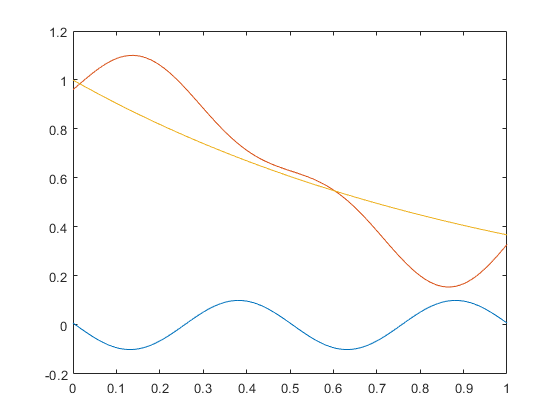


tempo = [0:0.01:T0];

figure()

plot(tempo,p2t(tempo) ,tempo,r2t(tempo) ,tempo,gt(tempo))